% KTX
clc, clear

addpath('functions')
imds = imageDatastore('images\train\KTX', 'LabelSource', 'foldernames', 'IncludeSubfolders',true);

tbl = countEachLabel(imds)

tbl = 1×2 table
    Label    Count
    _____    _____

     KTX      243 


% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, 0.7, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 1×2 table
    Label    Count
    _____    _____

     KTX      170 


% Load pretrained network
net = resnet50();

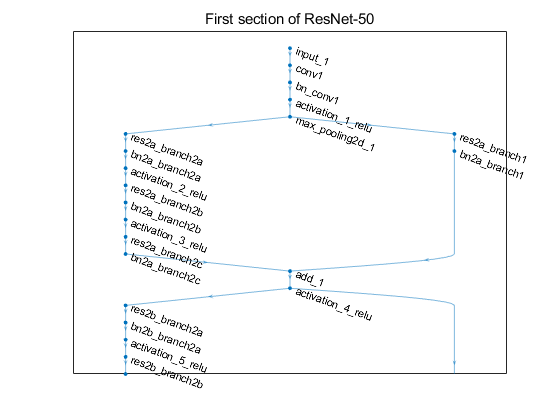

% Visualize the first section of the network.
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);

% Inspect the first layer
net.Layers(1)

ans =   ImageInputLayer - 속성 있음:

                      Name: 'input_1'
                 InputSize: [224 224 3]

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


% Inspect the last layer
net.Layers(end)

ans =   ClassificationOutputLayer - 속성 있음:

            Name: 'ClassificationLayer_fc1000'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   하이퍼파라미터
    LossFunction: 'crossentropyex'


% Number of class names for ImageNet classification task
numel(net.Layers(end).ClassNames)

ans = 1000

[trainingSet, testSet] = splitEachLabel(imds, 0.9, 'randomize');

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize;
tic
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet);
augmentedTestSet = augmentedImageDatastore(imageSize, testSet);

% Get the network weights for the second convolutional layer
w1 = net.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5);


% analyzeNetwork(net.Layers)
testImage = imread('sonata.png');
testImage2 = imresize(testImage,[224 224]);
classify(net,testImage2)

ans = categorical
     passenger car 


names = net.Layers(end).ClassNames;

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.
classifier = fitcsvm(trainingFeatures',trainingLabels,'KernelScale','auto','Standardize',true,...
    'OutlierFraction',0.05);
toc

경과 시간은 9.434293초입니다.


% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
[~,scores_train] = predict(classifier, trainingFeatures, 'ObservationsIn', 'columns');

[predictedLabels,scores] = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat = 1

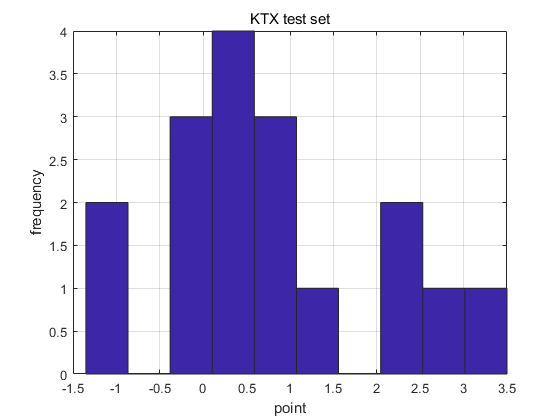

figure
hist(scores)
title('KTX test set')
xlabel('point')
ylabel('frequency')
grid()

% Display the mean accuracy
mean(diag(confMat))

ans = 1

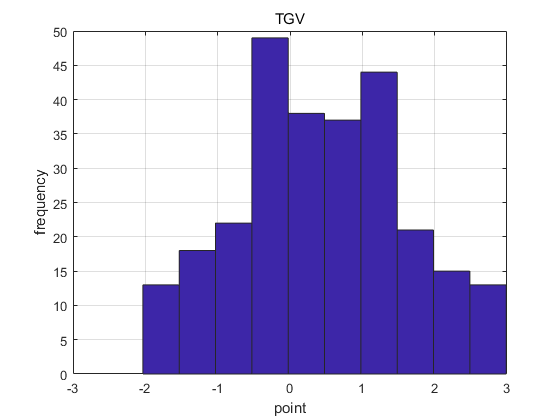

figure
imds_tgv = imageDatastore('images\train\TGV', 'LabelSource', 'foldernames', 'IncludeSubfolders',true);
augmentedTestSet = augmentedImageDatastore(imageSize, imds_tgv);

imageFeatures = activations(net, augmentedTestSet, featureLayer, 'OutputAs', 'columns');
[predictedLabels, scores_tgv] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');

idxs = randperm(length(imds_tgv.Files),9);
figure
for i=1:9
    subplot(3,3,i)
    j = idxs(i);
    imshow(readimage(imds_tgv,j))
    title(double(scores_tgv(j)))
end

figure
hist(scores_tgv)
title('TGV')
xlabel('point')
ylabel('frequency')
grid()

double(scores(4))

ans = 0.5976

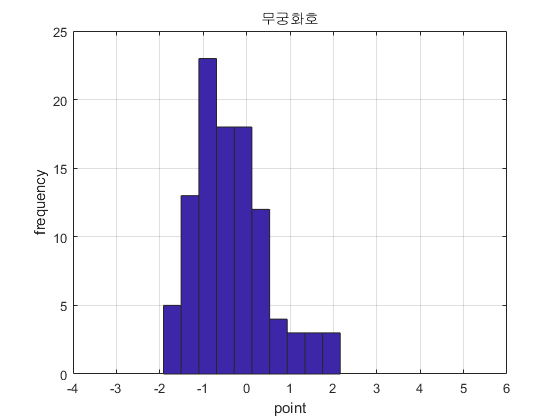

figure
imds_temp = imageDatastore('images\train\mugunghwa', 'LabelSource', 'foldernames', 'IncludeSubfolders',true);
augmentedTestSet = augmentedImageDatastore(imageSize, imds_temp);

imageFeatures = activations(net, augmentedTestSet, featureLayer, 'OutputAs', 'columns');
[predictedLabels, scores_mu] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
idxs = randperm(length(imds_temp.Files),9);
figure
for i=1:9
    subplot(3,3,i)
    j = idxs(i);
    imshow(readimage(imds_temp,j))
    title(double(scores_mu(j)))
end
figure
hist(scores_mu)
title('무궁화호')
xlabel('point')
ylabel('frequency')
grid()
xlim([-4 6])

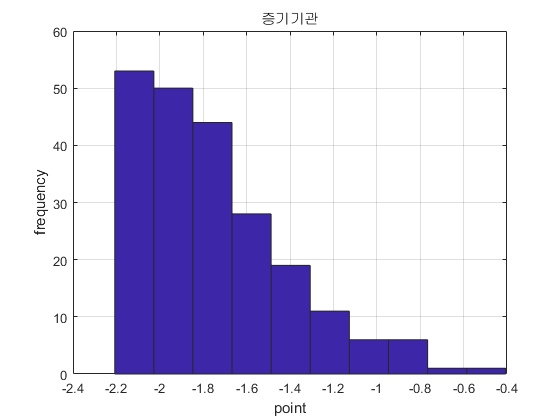

figure
imds_temp = imageDatastore('images\train\증기기관', 'LabelSource', 'foldernames', 'IncludeSubfolders',true);
augmentedTestSet = augmentedImageDatastore(imageSize, imds_temp);

imageFeatures = activations(net, augmentedTestSet, featureLayer, 'OutputAs', 'columns');
[predictedLabels, scores_jeung] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
idxs = randperm(length(imds_temp.Files),9);
figure
for i=1:9
    subplot(3,3,i)
    j = idxs(i);
    imshow(readimage(imds_temp,j))
    title(double(scores_jeung(j)))
end

figure
hist(scores_jeung)
title('증기기관')
xlabel('point')
ylabel('frequency')
grid()


scores_mean = trimmean(scores,15)

scores_mean = single
0.6869


tgv_mean = trimmean(scores_tgv,15)

tgv_mean = single
0.4100

mu_mean = trimmean(scores_mu,15)

mu_mean = single
-0.4265

jeung_mean = trimmean(scores_jeung,15)

jeung_mean = single
-1.7852

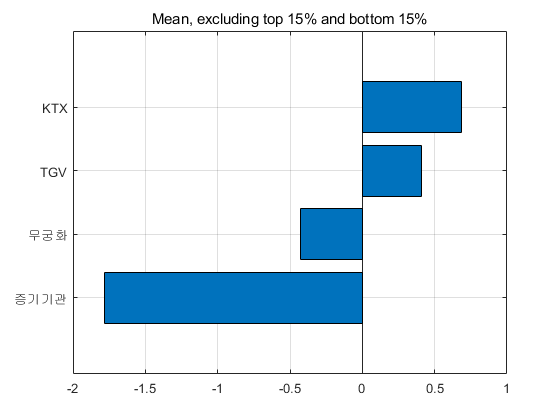


figure
barh([jeung_mean,mu_mean,tgv_mean,scores_mean])
yticklabels({'증기기관','무궁화','TGV','KTX',})
grid()
title('Mean, excluding top 15% and bottom 15%')

ktx_max = max(scores)

ktx_max = single
3.5000

% KTX의 test 이미지들 중 잘못 분류하는 것들
error_idx = [];
error_score = [];
good_idx = [];
good_score = [];
k=1;
g = 1;
for i=1:length(testSet.Files)
    testImage = readimage(testSet,i);
    ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
    imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
    [predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
    if score<0.5
        error_idx(k) = i;
        error_score(k) = score;
        k=k+1;
    elseif score>2
        good_idx(g) = i;
        good_score(g) = score;
        g = g+1;
    end
end

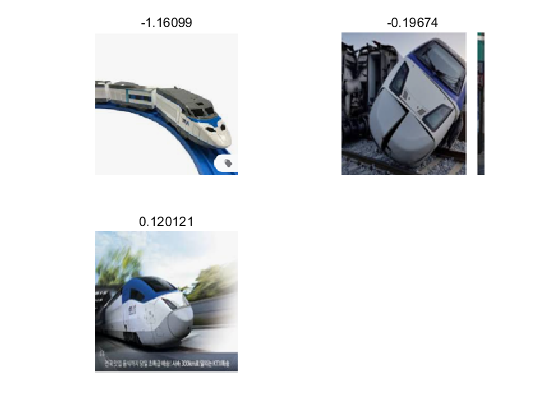

figure
idx = error_idx;
figure
for i=1:3
    subplot(2,2,i)
    j = idx(i);
    testImage = readimage(testSet,j);
    ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
    imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
    [predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
    
    imshow(testImage)
    title(error_score(i))
    
    
end

figure
idx = randperm(length(good_idx),4);
figure
for i=1:4
    subplot(2,2,i)
    j = idx(i);
    k = good_idx(j);
    testImage = readimage(testSet,k);
    ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
    imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
    [predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
    
    imshow(testImage)
    title(good_score(j))
    
end


% % figure
% % for i=1:30
% %     subplot(5,6,i)
% %     k = error_idx(i);
% %     testImage = readimage(testSet,k);
% %     ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
% %     imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
% %     [predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
% %
% %     imshow(testImage)
% %     title(error_score(i))
% %
% %
% % end
% %

testImage = imread('소나타_전방.png');
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
[predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
figure
imshow(testImage)
score


figure
testImage = imread('고양이.png');

ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
[predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
figure
imshow(testImage)
title(score)

figure
testImage = imread('사자.png');
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
[predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
figure
imshow(testImage)
title(score)


CVSVMModel = crossval(classifier);
[~,scorePred] = kfoldPredict(CVSVMModel);
outlierRate = mean(scorePred<0)